# Q3

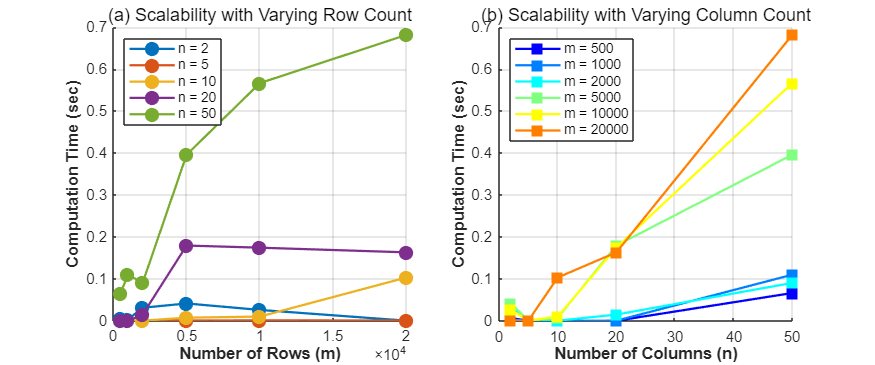

Figure saved as scaling_plot.png


%% Data Preprocessing
clc; clear;
opts = detectImportOptions('scaling_results.csv');  % Detect import options for CSV file
opts.VariableNamingRule = 'preserve';  % Preserve original variable names
data = readtable('scaling_results.csv', opts);  % Read CSV file into a table

% Sort data based on 'm' values in ascending order
[~, idx] = sort(data.m);
data = data(idx, :);

%% Plot Scalability Charts
figure('Position', [100 100 1200 500], 'Color','w')  % Set figure size and background color

% ========== Subplot 1: Effect of m while keeping n fixed ==========
subplot(1,2,1)  % Create the first subplot
hold on; grid on;
n_values = unique(data.n);  % Get unique values of n
colors = lines(length(n_values));  % Generate distinct colors for different n values

for i = 1:length(n_values)
    mask = (data.n == n_values(i));  % Select rows where n matches the current value
    plot(data.m(mask), data.("time(sec)")(mask),...  % Plot computation time against m
        'o-', 'LineWidth',1.5, 'MarkerSize',8,...  % Define line and marker properties
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...  % Set colors
        'DisplayName', sprintf('n = %d', n_values(i)))  % Set legend label
end

xlabel('Number of Rows (m)', 'FontSize', 11, 'FontWeight', 'bold')  % Label for x-axis
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')  % Label for y-axis
title('(a) Scalability with Varying Row Count', 'FontSize', 12)  % Chart title
legend('Location','northwest', 'FontSize', 9)  % Display legend

% ========== Subplot 2: Effect of n while keeping m fixed ==========
subplot(1,2,2)  % Create the second subplot
hold on; grid on;
m_values = unique(data.m);  % Get unique values of m
colors = jet(length(m_values));  % Generate distinct colors for different m values

for i = 1:length(m_values)
    mask = (data.m == m_values(i));  % Select rows where m matches the current value
    plot(data.n(mask), data.("time(sec)")(mask),...  % Plot computation time against n
        's-', 'LineWidth',1.5, 'MarkerSize',8,...  % Define line and marker properties
        'Color', colors(i,:), 'MarkerFaceColor', colors(i,:),...  % Set colors
        'DisplayName', sprintf('m = %d', m_values(i)))  % Set legend label
end

xlabel('Number of Columns (n)', 'FontSize', 11, 'FontWeight', 'bold')  % Label for x-axis
ylabel('Computation Time (sec)', 'FontSize', 11, 'FontWeight', 'bold')  % Label for y-axis
title('(b) Scalability with Varying Column Count', 'FontSize', 12)  % Chart title
legend('Location','northwest', 'FontSize', 9)  % Display legend

%% Save Figure
print -dpng -r300 scaling_plot.png  % Save the figure as a high-resolution PNG file

disp('Figure saved as scaling_plot.png')  % Print message confirming save operation

Using an m × n dimensional random matrix, TSQR computes the QR decomposition in parallel through MPI and records the calculation time. The left figure shows the trend of the calculation time changing with m when the n is fixed. It can be seen that the increase in the number of rows will affect the calculation time, but the growth rate varies from n. The figure on the right shows the calculation time changes with n when the m is fixed, indicating that larger m will cause the calculation cost to rise faster when n grows. Overall, TSQR is more sensitive to m, while the influence of n is more obvious when larger m is, which conforms to the computational characteristics of the Tall-Skinny structure.